# Efficiency Map of Motor Drive Unit

This script collects block parameters from Motor Drive Unit block and plots the motor efficiency contour map.

## Basic model

The "Basic" model of Motor Drive Unit uses Motor & Drive block from Simscape Driveline.

mdl = "MotorDriveUnit_refsub_Basic";
MotorDriveUnit_refsub_Basic_params
load_system(mdl)
blkpath = mdl + "/Motor & Drive (Driveline)";
info = MotorDriveUnit_getBlockInfo_Basic(blkpath)

info = struct with fields:
                                 MaxTorque_Nm: 420
                                  MaxPower_kW: 220
                               ResponseTime_s: 0.0200
                               Efficiency_pct: 95
             SpeedAtEfficiencyMeasurement_rpm: 2000
             TorqueAtEfficiencyMeasurement_Nm: 50
    MechanicalPowerAtEfficiencyMeasurement_kW: 10.4720
         NominalLossAtEfficiencyMeasurement_W: 551.1566
            IronLossAtEfficiencyMeasurement_W: 55.1157
          CopperLossAtEfficiencyMeasurement_W: 496.0409


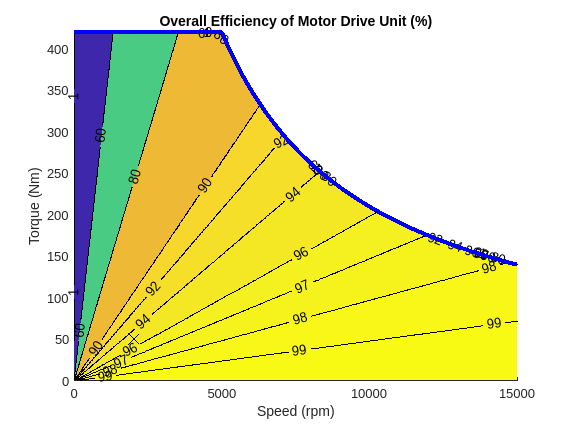

MotorDriveUnit_plotEfficiency_Basic( ...
  ... In road vehicle applications,
  ... maximum motor speed is determined by vehicle top speed,
  ... tire rolling radius, and reduction gear ratio. 
  MaxSpeed_rpm = 15000, ...
  ...
  MaxTorque_Nm = info.MaxTorque_Nm, ...
  MaxPower_kW = info.MaxPower_kW, ...
  Efficiency_pct = info.Efficiency_pct, ...
  SpeedAtEfficiencyMeasurement_rpm = info.SpeedAtEfficiencyMeasurement_rpm, ...
  TorqueAtEfficiencyMeasurement_Nm = info.TorqueAtEfficiencyMeasurement_Nm, ...
  ContourLevels_pct = [1 60 80 90 92 94 96 97 98 99], ...
  PlotResolution = 500 );

*Copyright 2021-2023 The MathWorks, Inc.*